set(gcf,'Visible','on')
sim = robot_kinematic_sim_kuka();

r = rateControl(20);

force = [0;0;0; 0;0;0; 1]*1e-1

force =          0
         0
         0
         0
         0
         0
    0.1000



N = 1000

N = 1000

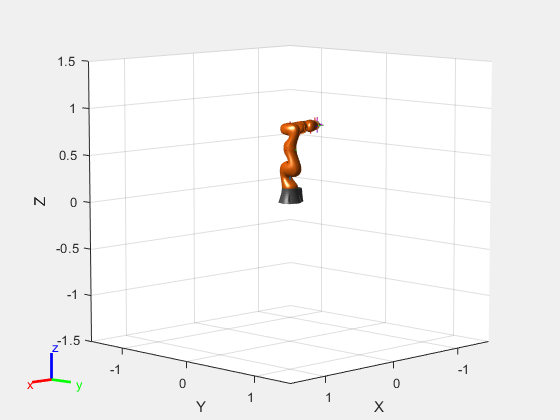


qq = NaN([7 N]);

for i = 1:1
    qq(:,i) = sim.q;
    sim.set_q(sim.q + sim.augmented_jacobian("Stereographic")' * force);
    sim.show_plot();
    waitfor(r);

end

plot(wrapToPi(qq'))


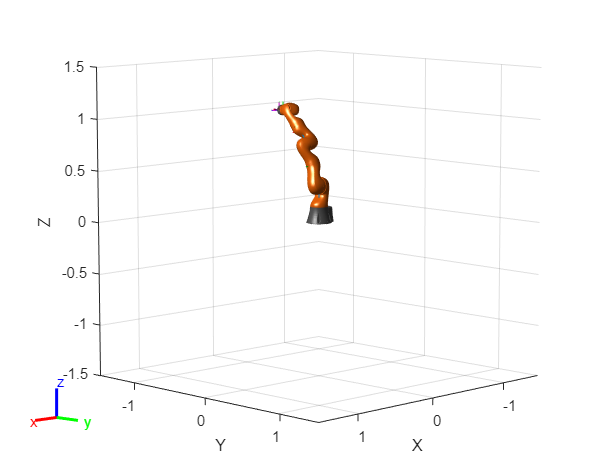

sim = robot_kinematic_sim_kuka();
sim.set_q(sim.robot.randomConfiguration);
sim.show_plot();


J = sim.augmented_jacobian("Stereographic")

J =    -0.0000    0.9855    0.0560   -0.9739   -0.0241   -0.9639    0.2113
    0.0000    0.1699   -0.3248    0.1905   -0.6270   -0.1921   -0.9732
    1.0000    0.0000    0.9441    0.1233    0.7786   -0.1845   -0.0904
    0.5098    0.1184    0.2551    0.1032    0.1026   -0.0204   -0.0000
    0.0405   -0.6865   -0.0008    0.2943    0.0205   -0.0159   -0.0000
   -0.0000   -0.5093   -0.0154    0.3605    0.0196    0.1233   -0.0000
    1.0000   -0.0344    1.0277    0.0320    0.0000         0         0



inv(J')

ans =    -0.8410    0.6449    0.7914    1.5596   -0.4447   -1.7257    0.7809
   -0.1302    0.1335    0.1210    0.3250   -0.2047   -0.3507   -0.7799
   -0.5642    0.0699    0.5468    0.1471    1.1638   -0.2587   -0.8402
    3.6852    0.3125   -3.5829    0.2375   -0.2196    0.1841    1.4019
    4.2180   -4.0627   -4.0343   -6.6198    0.8014    1.9393   -1.5577
   -6.4667    4.8817    6.0790   12.1036   -1.9866   -6.0329    3.6633
   -0.4856   -0.0646    1.4434    0.0000   -1.0843    0.0863    0.1886


pinv(J(1:6,:)')

ans =    -0.5683    0.6812   -0.0194    1.5596    0.1644   -1.7742    0.6750
   -0.0927    0.1385    0.0094    0.3250   -0.1208   -0.3574   -0.7945
   -0.6168    0.0629    0.7032    0.1471    1.0462   -0.2494   -0.8197
    2.7992    0.1947   -0.9492    0.2375   -2.1980    0.3416    1.7459
    3.0385   -4.2195   -0.5279   -6.6198   -1.8325    2.1488   -1.0996
   -4.5579    5.1354    0.4049   12.1036    2.2757   -6.3720    2.9221



F = [1;2;3;4;5;6;100]

F =      1
     2
     3
     4
     5
     6
   100



tau = J'*F

tau =   105.2420
   -8.1282
  105.9282
    7.0251
    1.6884
   -1.3231
   -2.0064



inv(J')*tau

ans =     1.0000
    2.0000
    3.0000
    4.0000
    5.0000
    6.0000
  100.0000


pinv(J(1:6,:)')*tau

ans =   -55.1715
   -5.7338
   13.8374
  186.4628
  247.9175
 -387.0984
